Ejemplo de diseño de filtro digital

autor: Filipuzzi, Fernando Rafael

versión: 20230314

Matlab:2022b

function [B,A]=mi_lp2hp(Bs,As, wc)

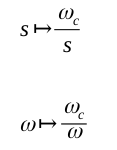

    
    syms s;
    H(s)=poly2sym(Bs,s)/poly2sym(As,s);

    H(s)=collect(H(wc/s));
    
    [num,den]=numden(H(s));
    B=sym2poly(num);
    A=sym2poly(den);

end